**Importing parameters and drawing the initial image**

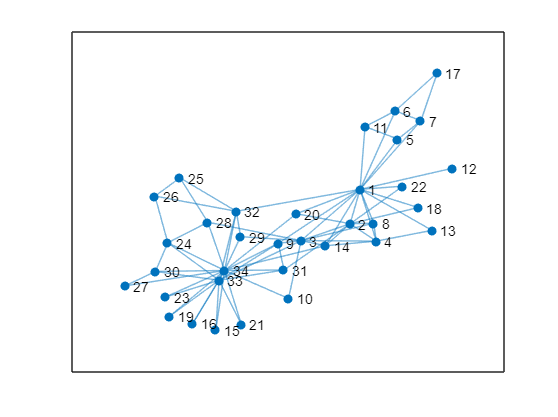

clc;clear;
%% Select different network
% s=[1,1,1,1,2,2,5,10,10,9,3,3,3,9,9,6,6,9,7]'; %figure2 example
% t=[2,5,8,10,5,8,8,6,3,1,6,7,4,2,5,4,7,8,4]';
 load('karate.mat');
% load('socdolphins.mat');
% load('football.mat');
% load('caGrQc.mat');
s=data(:,1);
t=data(:,2);

G = graph;  %generate empty graph
G = addedge(G,s,t); %add nodes and lines
figure(1)
plot(G)

**Calculate degree and cosine similarity**

degree = centrality(G,'degree');
n=length(degree);
k=length(s);
Graph=zeros(n);
for i=1:k
    Graph(s(i,1),t(i,1))=1;
    Graph(t(i,1),s(i,1))=1;
end
d=1/n;

%% Calculate cosine similarity
    sim = Graph*Graph;                 
    for i=1:n
        a=sum(Graph(i,:).^2);
        for j=i+1:n
            b=sum(Graph(j,:).^2);
            sim(i,j)=sim(i,j)/sqrt(a*b);
            sim(j,i)=sim(i,j);
        end
    end
    for i=1:n
        sim(i,i)=0;
    end
       sim1=(sim>0);
       M=sum(degree);
       pp=M/(n*(n+1));

**Clustering**

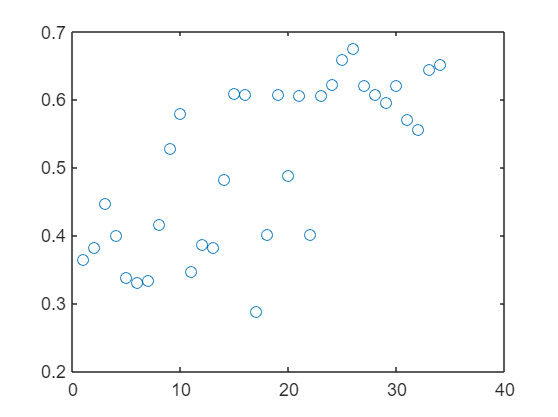

     maxQ=0;
     max_result=zeros(n);
% Choose standard and Beta
     standard=0.9;
     Beta=2;
     c=Beta*pp;
% initial stage
    a=0:d:1-d;
    q=1:n;
    p=zeros(1,n);
% Start the loop
for t=1:15
    for i=1:n
        a(1,i)=a(1,i)+1/sum(sim1(i,:))*sum((sim(i,:)).*sin((a-ones(1,n).*a(1,i))))...
        -1/M*sum(c.*sin((a-ones(1,n).*a(1,i))));
    end

% Calculation of order parameters
%     r=0;
%     for i=1:n-1
%         for j=i+1:n
%             r=r+cos((a(j)-a(i)));
%         end
%     end
%     r=r/(n*(n-1)/2)
    
% Classification according to local order parameters
    [a1,I] = sort(a,'ascend');
    g=1;h=1;r=0;
    cluster_result=zeros(n);
    cluster_result(g,h)=I(1);
    h=h+1;flag=1;m=0;
    for i=2:n
            r=(r*(h-2)+exp(1*(-a1(i)+a1(1,flag))))/(h-1);
            if(r>standard)
                cluster_result(g,h)=I(1,i);
                h=h+1;
            else
                r=0;h=1;
                g=g+1;flag=i;
                cluster_result(g,h)=I(i);
                h=h+1;
            end
    end
    
% Modularity calculation
     Q=0;
        for i=1:n
            [g,h]=find(i==cluster_result);
            for j=i+1:n
                b=sum(cluster_result(g,:)==j);
            Q=Q+2/M*(Graph(i,j)-degree(i)*degree(j)/M)*b;
            end
        end
% undate best cluster result
        if(Q>maxQ)
            maxQ=Q;
            max_result=cluster_result;
            amax=a;
        end
end
% Export and visualize results
     figure(2)
    plot(q,amax,'o')

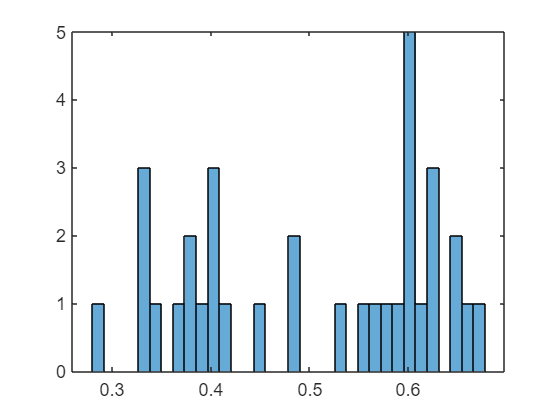

    figure(3)
     histogram(amax,n)

     max_result

max_result =     17     6     7     5    11     1     2    13    12     4    18    22     8     3    14    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     9    32    31    10    29    23    21    28    19    16    15    27    30    24    33    34    25    26     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     